# Homework 3

***Ryan Campbell, Christian Molina***

*Math 128A SS2 - 2021*

*due Monday, 08/30/2021*

### 1. (33 Points)

**(a)**  Derive a difference formula to approximate the first derivative at x using function values at x−2h, x−h, and x.  What is the order of accuracy of the approximation?

**(b)**  Derive  a  difference  formula  to  approximate  the  second  derivative  at x using  function values at x−2h, x−h, and x.  What is the order of accuracy of the approximation?

**(c)  **Apply the difference formulas to f(x) = exp(−x) at x= 0 to approximate f′(0) and f′′(0).  Use increasingly smaller values of h, and make tables of the approximate derivatives and the absolute errors of each of the approximations.

% https://www.youtube.com/watch?v=HOrIrdS1EZA

**(d)  **Plot the absolute errors vs.1/h on a log-log graph.

**(e)  **Explain how the table of errors and the graph of the errors demonstrate the order of convergence.

### 2.  (30 points)

**(a)**  For the data below find the least squares polynomials of degrees 1, 2 3, 4, and 6.  You may find the MATLAB commands `polyfit `and `polyval `useful.  In Python, the same commands are available in the `numpy `library.

x_values = [0.000 0.143 0.286 0.429 0.571 0.714 0.857 1.000];
y_values = [0.103 0.121 0.179 0.250 0.444 0.519 0.897 1.269];
x_points = linspace(0,1);

p1 = polyval(polyfit(x_values, y_values, 1),x_points);
p2 = polyval(polyfit(x_values, y_values, 2),x_points);
p3 = polyval(polyfit(x_values, y_values, 3),x_points);
p4 = polyval(polyfit(x_values, y_values, 4),x_points);
p6 = polyval(polyfit(x_values, y_values, 6),x_points);

**(b)**  Make plots of the data and the polynomials on the same graph.

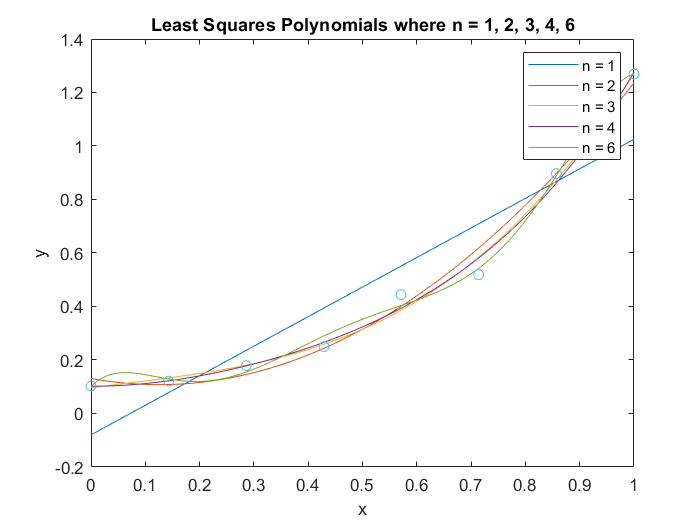

% There is an x-axis issue, for some reason, polyval is having the
% polynomials plot values from 0 to 100 - when it is fitted for 100 points
% between 0 and 1. 
figure(1);
plot(x_points, p1);
hold on;
plot(x_points, p2); plot(x_points, p3); plot(x_points, p4); plot(x_points, p6); plot(x_values, y_values,'o');
hold off;
title("Least Squares Polynomials where n = 1, 2, 3, 4, 6");
legend('n = 1', 'n = 2', 'n = 3', 'n = 4', 'n = 6');
xlabel('x'); ylabel('y');

**(c)**  For each least squares polynomial,P(x), compute the error


$$E_2 = \sum_{j}({y_j - P(x_j))^2}$$


% Calculating the error for each least sqaures polynomial
err1 = sum((y_values-polyval(polyfit(x_values, y_values, 1),x_values)).^2)

err1 = 0.1673

err2 = sum((y_values-polyval(polyfit(x_values, y_values, 2),x_values)).^2)

err2 = 0.0150

err3 = sum((y_values-polyval(polyfit(x_values, y_values, 3),x_values)).^2)

err3 = 0.0085

err4 = sum((y_values-polyval(polyfit(x_values, y_values, 4),x_values)).^2)

err4 = 0.0081

err6 = sum((y_values-polyval(polyfit(x_values, y_values, 6),x_values)).^2)

err6 = 0.0045

**(d)**  Which polynomial do you think best approximates the data?  Does increasing the degree of the least squares polynomial always decrease the error?  Does increasing the degree of the least squares polynomial give a better approximation?  Explain.

*The polynomial that best approximates the data is that of the 4th-degree polynomial. Issues begin to occur once we increase the degree of polynomials since it would call for more oscillations to attempt to hit all data points. *

### 3.  (37 points) 

Let $f(x) = (x + 1)\exp(\frac{-3(x+1)^2}{4})$

**(a)**  Find the third degree Taylor polynomial,S(x), of f(x) about x= 0.

% Sources:
% https://www.mathworks.com/help/symbolic/sym.taylor.html
% ref: T = taylor(f, 'Order', 8)

syms x
func_3a = (x + 1)*exp((-3*(x+1).^2)/4);
f =@(x) (x + 1).*exp((-3.*(x+1).^2)/4);
S = taylor(func_3a,x,'ExpansionPoint',0,'Order',4);
p3a = ['Taylor Expansion of f(x): '];
disp(p3a); disp(S);

Taylor Expansion of f(x): 


$$\frac{15\,{\mathrm{e}}^{-\frac{3}{4}}\,x^{3}}{16}-\frac{9\,{\mathrm{e}}^{-\frac{3}{4}}\,x^{2}}{8}-\frac{{\mathrm{e}}^{-\frac{3}{4}}\,x}{2}+{\mathrm{e}}^{-\frac{3}{4}}$$

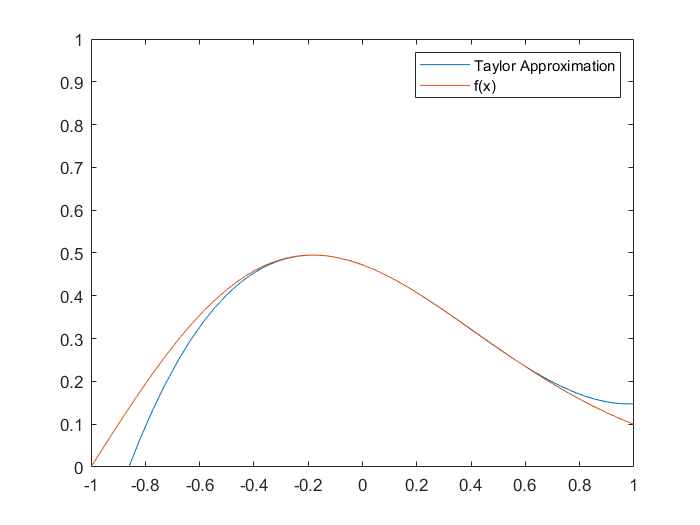


figure(2);
fplot([S f]);
legend('Taylor Approximation', 'f(x)');
xlim([-1 1]);
ylim([0,1]);

**(b)**  Find the third degree polynomial,P(x), that minimizes


$$\int_{-1}^{1}(f(x)-P(x))^2dx$$


Solve this problem by using orthogonal polynomials.You could, but you need not, preform the integration by hand.  You can perform the necessary integration using symbolic computation using, for example, Maple, Mathematica,or Wolfram Alpha.  State what program you used and give the results.  Alternately, you may perform the integration numerically.  In matlab the routine to use is `integral`. In python, the corresponding routine is `quad `from the library `scipy.integrate`. Examples are given below.  We will learn about how these methods work later in the quarter.

disp("With the following legendre polynomials: ")

With the following legendre polynomials: 


legendreP(0,x)

$$ans = 1$$

legendreP(1,x)

$$ans = x$$

legendreP(2,x)

$$ans = \frac{3\,x^{2}}{2}-\frac{1}{2}$$

legendreP(3,x)

$$ans = \frac{5\,x^{3}}{2}-\frac{3\,x}{2}$$


nint0 =@(x) legendreP(0,x).*(x+1).*exp((-3.*(x+1).^2)./4); nint1 =@(x) legendreP(1,x).*(x+1).*exp((-3.*(x+1).^2)./4);
nint2 =@(x) legendreP(2,x).*(x+1).*exp((-3.*(x+1).^2)./4); nint3 =@(x) legendreP(3,x).*(x+1).*exp((-3.*(x+1).^2)./4);

dint0 =@(x) legendreP(0,x).^2; dint1 =@(x) legendreP(1,x).^2;
dint2 =@(x) legendreP(2,x).^2; dint3 =@(x) legendreP(3,x).^2;

c0 = integral(nint0,-1,1) / integral(dint0,-1,1); c1 = integral(nint1,-1,1) / integral(dint1,-1,1);
c2 = integral(nint2,-1,1) / integral(dint2,-1,1); c3 = integral(nint3,-1,1) / integral(dint3,-1,1);

err_integrand =@(x) ((x+1).*exp((-3.*(x+1).^2)./4) - (c0*legendreP(0,x) + c1*legendreP(1,x) + c2*legendreP(2,x) + c3*legendreP(3,x))).^2;

disp("With third degree polynomials that are orthogonal, the error is minimized to:")

With third degree polynomials that are orthogonal, the error is minimized to:


disp(integral(err_integrand,-1,1))

   1.9678e-04




p =@(x) c0*legendreP(0,x) + c1*legendreP(1,x) + c2*legendreP(2,x) + c3*legendreP(3,x)

p = function_handle with value:
    @(x)c0*legendreP(0,x)+c1*legendreP(1,x)+c2*legendreP(2,x)+c3*legendreP(3,x)


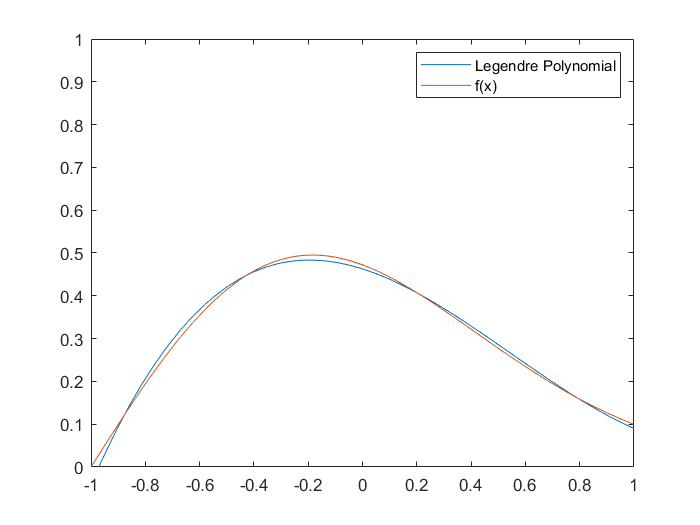


figure(3);
fplot([p func_3a]);
legend('Legendre Polynomial','f(x)')
xlim([-1 1]);
ylim([0 1]);

**(c)**  Find the third degree polynomial,Q(x), that interpolates f at the Chebyshev extrema points: ±1,±0.5.

*Let *$Q(x) = \tilde{T}_n(x) - P_n(x)$*, where P(x) is our third degree polynomial from part (b), then:*

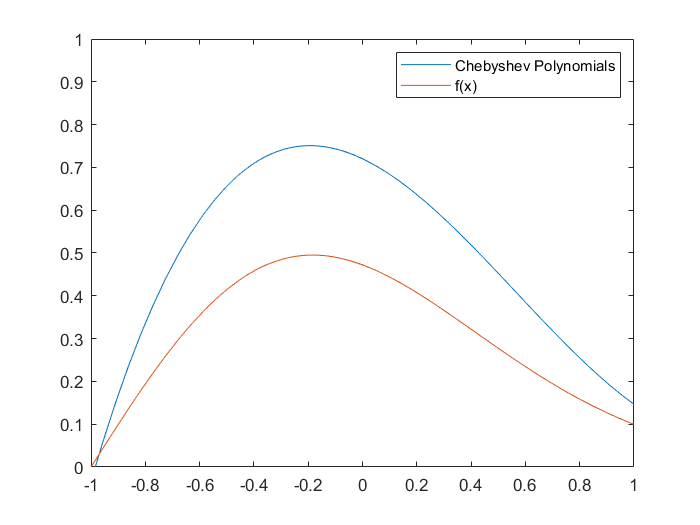

% https://www.mathworks.com/help/symbolic/sym.chebyshevt.html
% http://inis.jinr.ru/sl/M_Mathematics/MRef_References/Mason,%20Hanscomb.%20Chebyshev%20polynomials%20(2003)/C0355-Ch06.pdf
% https://www.youtube.com/watch?v=R5n5pvLvBo0&list=WL&index=2&t=56s


cheb_int0 =@(x) ((x+1).*exp((-3.*(x+1).^2)./4).*chebyshevT(0,x)) ./ ((1 - x.^2).^(1/2));
cheb_int1 =@(x) ((x+1).*exp((-3.*(x+1).^2)./4).*chebyshevT(1,x)) ./ ((1 - x.^2).^(1/2));
cheb_int2 =@(x) ((x+1).*exp((-3.*(x+1).^2)./4).*chebyshevT(2,x)) ./ ((1 - x.^2).^(1/2));
cheb_int3 =@(x) ((x+1).*exp((-3.*(x+1).^2)./4).*chebyshevT(3,x)) ./ ((1 - x.^2).^(1/2));
a0 = integral(cheb_int0,-1,1); a1 = integral(cheb_int1,-1,1);
a2 = integral(cheb_int2,-1,1); a3 = integral(cheb_int3,-1,1);

q =@(x) (a0/2)*chebyshevT(0,x) + a1*chebyshevT(1,x) + a2*chebyshevT(2,x) + a3*chebyshevT(3,x);

figure(3);
fplot([q func_3a]);
legend('Chebyshev Polynomials','f(x)')
xlim([-1 1])
ylim([0 1])

**(d)**  Make plots of f,S,P, and Q, and plots of the differences |f−S|, |f−P|, and |f−Q| on the interval [−1,1]. Comment on the different approximations? What are the advantages of each of the approximations?

### 4.  (30  BONUS  points)

Write  a  routine  that  takes  as  input x and y values  from  data  points and the polynomial degree n and returns the coefficients of the discrete least squares polynomial  approximation.   Instead  of  using `polyfit `as  in  Problem  (2),  your  routine  should form and solve the matrix form of the normal equations.  Use your routine and the MAT-LAB command `polyval `to find and plot the least squares polynomials of degree 3, 4, and 6 for the data given in Problem (2).  Compare to those from Problem (2).  You may want to examine the errors, $E_2$, or the differences between the coefficients.  Comment on your results.

x_data = [1:10]; y_data=[1:10];
normal = normEq(x_data,y_data, 3)

Unrecognized function or variable 'normEq'.

function normEq = normalEquations(x_data,y_data,n)
    m = length(x_data);
    % Generate the A = [m x n] matrix
    A = zeros(m,n)

end

### 5.  (20 BONUS points)

**(a) ** Let $L_n$ represent the degree n Legendre polynomial.  Show that for any polynomial p of degree less than n,


$$\int_{-1}^{1} L_n(x)p(x)dx = 0$$


That is, the $n^{th}$ degree Legendre polynomial is orthogonal to all polynomials of degree less than n.  You may without proof that the Legendre polynomials are an orthogonal basis.

**(b)**  Let $\tilde{L_n}$ represent the $n^{th}$ degree monic Legendre polynomial.  Show that


$$\Vert\tilde{L_n}\Vert_2^2 \leq \Vert\tilde{p_n}\Vert_2^2$$


for all monic polynomial of degree n, $\tilde{p_n}$, where the norm is


$$\Vert{f}\Vert_2^2 = \langle f,f \rangle = \int_{-1}^{1}(f(x))^2dx$$


Hint: Let $\omega(x) = \tilde{p_n}(x) - \tilde{L_n}(x)$, and compute $\Vert\tilde{p_n}\Vert_2^2$

This result shows that the degree n monic Legendre polynomial is the degree n monic polynomial with smallest 2-norm.  The results from both part (a) and (b) are importantfor high-order accurate integration methods, specifically Gaussian quadrature.

### 6.  (10 BONUS points) 

Express the Legendre polynomials $P_0, ... , P_6$ of degrees 0 through 6 as monomial expansions.  That is, for each j= 0,...,6, find the coefficients of in the expansion


$$P_j(x) = a_0 + a_1x + ... + a_jx^j$$


Comment on your findings.

### 7.  (30  BONUS  points) 

To  solve  the  normal  equations  for  a continuous  least  squares problemon  [a,b],  we  can  solve  a  linear  system $A \underline{c} = \underline{b}$, where $A_{ij} = \int_a^b\phi_i(x)\phi_j(x)dx$ and $b_{j} = \int_a^b\phi_j(x)f(x)dx$.

**(a)**  Write a routine to form the matrix A for $\phi_i(x) = x^i$ that takes the inputs n, the degree of the polynomial and a and b, the endpoints of the interval.  (You may or may not have already done this for an earlier problem.  If it wasn’t this general before, edit your code to generalize it in this way.)  Form the matrix A for polynomials of degrees n= 2,4,6,...,12 on the interval [0,2] and calculate the condition numbers of the matrices.  You may usethe Matlab command `cond`.  You only need to report the condition numbers,  not thematrices.

**(b)**  Repeat part (a) for $\phi_i(x) = L_i(x)$, the $i^{th}$ Legendre polynomial.  You will be writing a new routine to form A when $\phi_i(x) = L_i(x)$.

**(c)**  Comment on your results.